% Choix du pas
rho = 0.1;
test = 1;
compteur = 1;
precision = 1.e-3;
maxiter = 100;    

ftest_array = double.empty;
cont = 1;
rhos = [(1/2)*rho, rho, 2*rho]

rhos =     0.0500    0.1000    0.2000


    
    for i = 1:numel(rhos)  
        aux = X.*(1 - rhos(i).*g);
        x1 = aux(1);
        x2 = aux(2);
        ftest_array(cont) = ma_function(x1,x2);
        cont = cont + 1;      
    end
    
    disp(ftest_array)

    1.8016    1.8065    1.8259



    
    ftest = min(ftest_array)

ftest = 1.8016

Mise à jour de l'algorithme précédemment implémenté, mise à jour de l'étape à chaque itération :

clear all; clc;

Affichage de la fonction :

[x,y] = meshgrid(-4:.1:4, -4:.1:4);
z = ma_function(x,y);
figure(1)
clf
hold on
surfc(x,y,z)
view(3)

Initialisation :

% Point Initial
X = [3; -3];

% Choix du pas
rho = 0.1;
test = 1;
compteur = 1;
precision = 1.e-3;
maxiter = 100;

while test
    compteur = compteur + 1;
    
    % Affichage progression de X
    x = X(1);
    y = X(2);
    z = ma_function(x,y);
    plot3(X(1), X(2), z + 0.1, '.r', 'MarkerSize', 15);
    view(3)
    pause(.1)
    
    % Calcul du gradient
    g = gradient_ma_fonction(x,y);

    % Mise à jour de X
    Xold = X;
    
    %  adaptation du pas à chaque itération
    ftest_array = double.empty;
    cont = 1;
    rhos = [(1/2)*rho, rho, 2*rho];
    
    for i = 1:numel(rhos)  
        aux = X.*(1 - rhos(i).*g);
        x1 = aux(1);
        x2 = aux(2);
        ftest_array(cont) = ma_function(x1,x2);
        cont = cont + 1;      
    end
    
    ftest = min(ftest_array); 
    index_optimal = find(ftest_array == ftest);
 
    if ftest <= z
        rho = rhos(index_optimal);
        X = X - rho.*g.*X;
       
    else
        rho = rho/4;
    end
        
    test = norm(Xold - X) > precision && compteur < maxiter;
end
if compteur == maxiter
disp('warning: Nombre d"iteration maximum atteint')
end

Affichage dernier point :

x = X(1);
y = X(2);
z = ma_function(x,y);
plot3(X(1), X(2), z+.1, '*g', 'MarkerSize', 15)

ans = 100

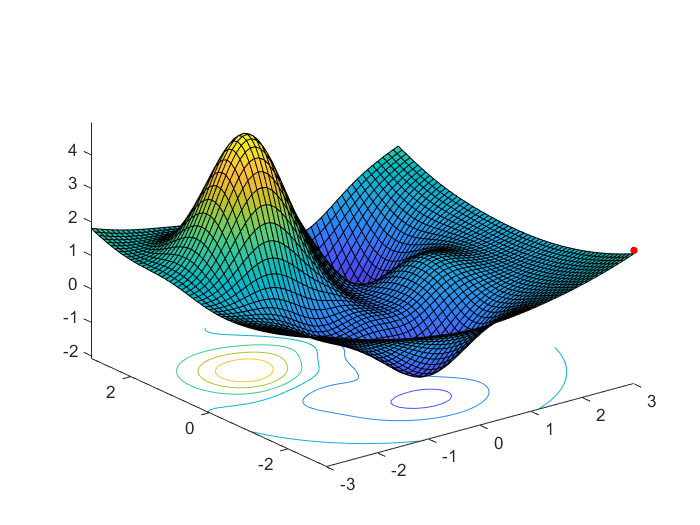

intMesh = 3;
[x,y] = meshgrid(-intMesh:.1:intMesh, -intMesh:.1:intMesh);
z = ma_function(x,y);
figure(1)
clf
hold on
surfc(x,y,z)
view(3)

X = [3,-3];
x = X(1);
y = X(2);
z = ma_function(x,y);

C = {'.k','.b','.r','.g','.y','.c','.m', ... 
     '.k','.b','.r','.g','.y','.c','.m', ...  
     '.k','.b','.r','.g','.y','.c','.m'};
plot3(X(1), X(2), z + 0.1, C{3}, 'MarkerSize', 15);